# Numerical Comparisons 

The current version is updated in primo January, 2023.

*Clean workspace, layout settings:*

clear;
clc;
close all;
base.layout();

In this workbook, we deal with the following experiments:

- Along the path of actual population weights, $\nu_t$, how does an infinite horizon solution compare to a steady state approximation?

- How do the finite horizon version of the model compare to an infinite horizon model in terms of *accuracy *and *solution time?*

- How long does it take to solve the model with various methods:

                (i)     Finite horizon EGM,

                (ii)    Infinite Horizon, time-dependent policy function, EGM, 

                (iii)   Infinite Horizon, time-dependent policy function, VFI

                (iv)   Infinite Horizon, SS approximation, EGM

                (v)    Infinite Horizon, SS approximation, VFI

## 1. Settings

Load calibration from the Argentina case:

load('ArgentinaParameters.mat','out');
load('ArgentinaTargets.mat','target');

Define settings for grids:

- approx.n: Number of gridpoints for $\tau_t$ in approximation of labor function.

- approx.nn: Number of gridpoints for $\tau_{t+1}$ in approximation of labor function.

- approx.s, approx.ss: Shape parameters used in nonlinear grid functions.

approx = struct();
[approx.n, approx.nn, approx.s, approx.ss] = deal(250,250,0.7,1.2);

Store all timings in the 'time' struct (create an empty one here).

time = struct();

Store all solutions in the v (versions) struct:

v = struct();

 Add settings for numerical tolerances for stopping:

- np.tol_diff: Maximum difference between two iterations when identifying a fixed point.

- np.tol_solver: Maximum tolerance for numerical solvers.

- np.max_iter: Upper bound on number of iterations applied in various algorithms.

- np.n_h: Number of gridpoints in the grid of $h$

- np.n_nu: Number of gridpoints in the grid of $\nu_$

- np:n_test: Size of grid of taxes to test if the algorithm has converged.

np = struct();
[np.tol_diff, np.tol_solver, np.max_iter, np.n_h, np.n_nu, np.n_test] = deal(1e-5,1e-7,50,250,10,25);
np_td = np;
np_td.n_nu = 1; % only one gridpoint is needed for the time-dependent functions

## 2. Labor function approximation:

Time setting up the labor equilibrium function:

tic
hfunc = IH.h_EE_approximation(out.par,approx);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.laborEquilibriumApproximation = toc;

From this, define relevant grids:

grids= struct();
grids.h  = linspace(hfunc(1,0),hfunc(0,1),np.n_h); 
grids.nu = linspace(min(out.par.nu_v), max(out.par.nu_v), np.n_nu);
grids.test = linspace(0.01, 0.99, np.n_test); 
grids_td = grids;
grids_td.nu = out.par.nu_v(end);

## 3. Finite Horizon, EGM solution

Time the solution time for the EGM, finite horizon solution approach:

tic
[v.FH_TD_EGM.sol, v.FH_TD_EGM.par] = SolveF.identify_policy(out.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.FH_TD_EGM = toc;

## 4. Infinite horizon, time-dependent, EGM

Apply gradient free solver to identify the terminal policy:

tic
[sample,dif,maxdiff,x,tau_cell,tau_m_cell,h] = IH.GradientFree_Policy(out.par,np_td,grids_td,hfunc,nan);
time.IH_TD_EGM_TerminalPolicy = toc;

Time the gradient free solver to identify path of policies:

tic
[v.IH_TD_EGM.sol, v.IH_TD_EGM.par] = IH.identifyPolicy(out.par, np_td, grids_td, hfunc, nan);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.IH_TD_EGM = toc;
v.IH_TD_EGM.sim = SolveF.sim_c_unique(v.IH_TD_EGM.par,v.IH_TD_EGM.sol);

## 5. Infinite Horizon, steady state, EGM

In this exercise, we start by recalibrating the model to reflect the year 2010 as a steady state. Then, given parameter values, we identify the policy function on the grid of $\nu_t$ as observed in the data. 

[IH_par, ~, IH_hfunc] = IH.cal_ss_c(out.par, target, approx, np);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Set grid of $\nu$ to observed path:

grids.nu = unique(IH_par.nu_v);
np.n_nu = length(grids.nu);
[~,~,~,x,IH_tau,IH_tau_m, IH_h] = IH.GradientFree_Policy(IH_par, np, grids, IH_hfunc, nan);

Use this to identify tax policy function:

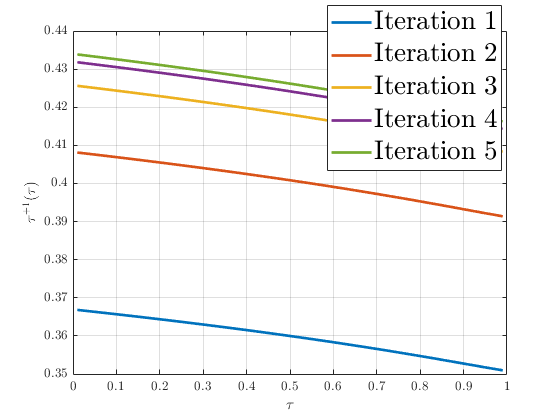

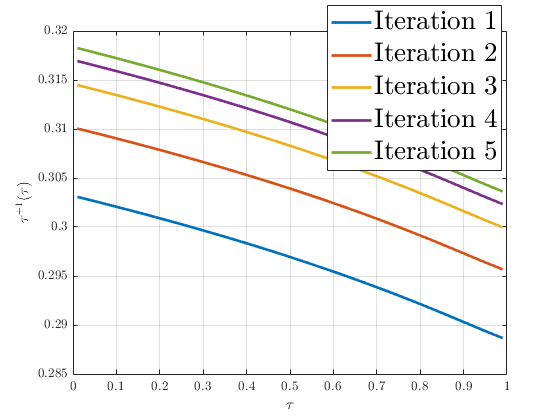

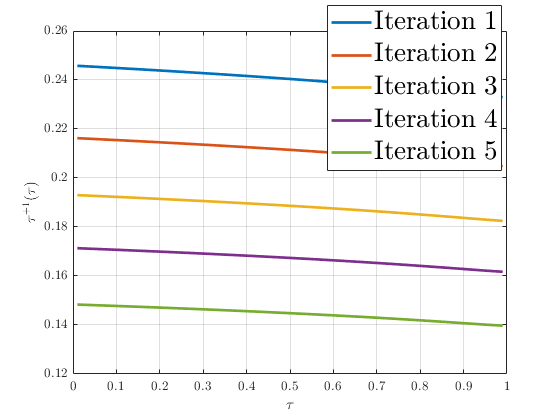

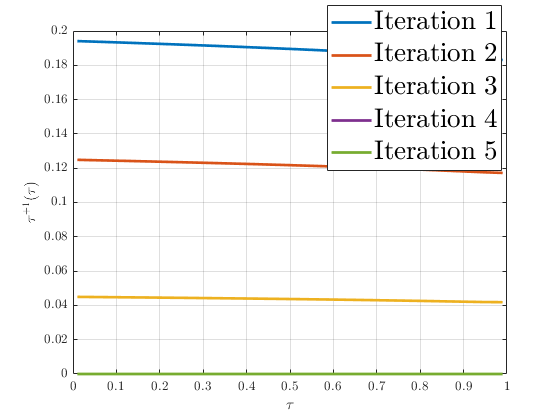

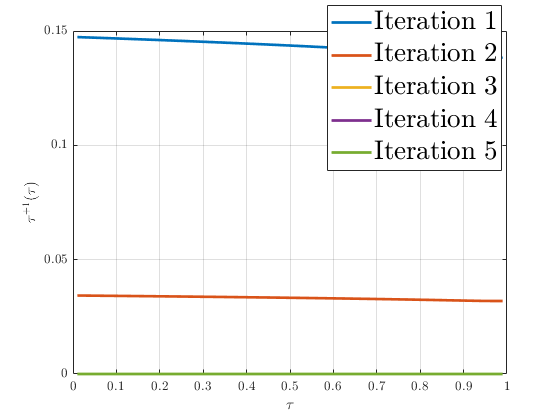

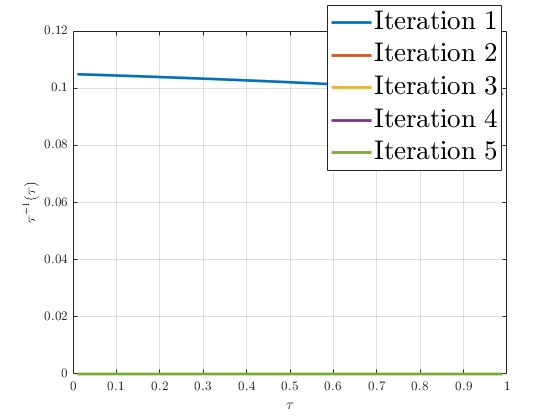

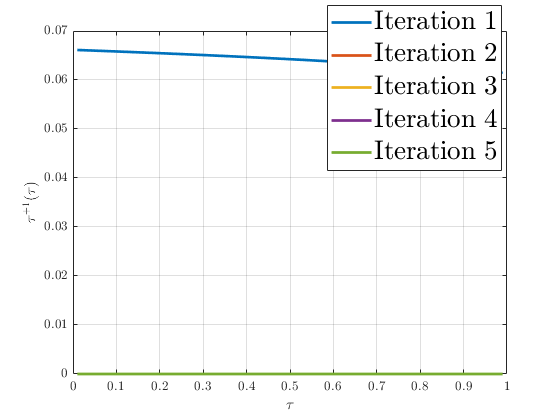

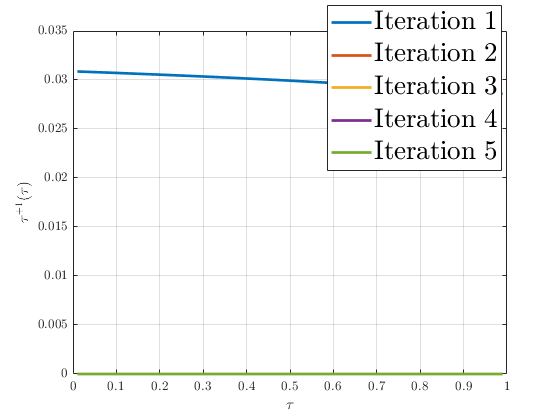

tauSample = cell2mat(IH_tau);

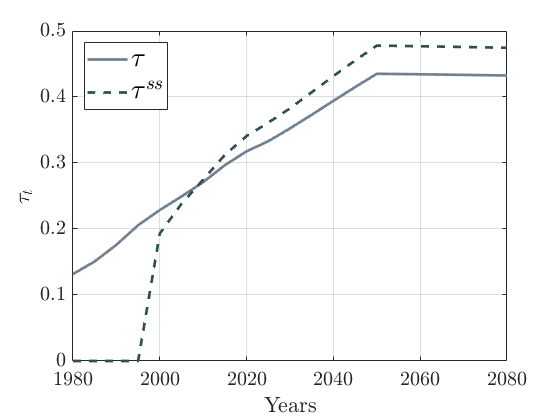

taumSample = cell2mat(IH_tau_m);
nuSample  = NaN(length(tauSample),1);
hSample   = cell2mat(IH_h);
count = 1;
for i=1:np.n_nu
    nuSample(count:count+length(IH_tau{i})-1)=repmat(grids.nu(i),length(IH_tau{i}),1);

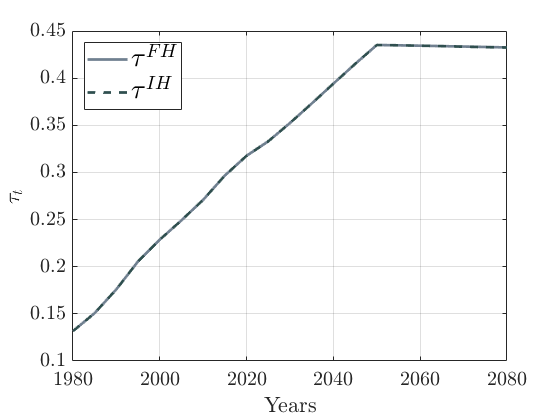

    count=count+length(IH_tau{i});

end
F_IH_ss = scatteredInterpolant(nuSample,hSample,tauSample,'linear','nearest');
F_ss_tax= scatteredInterpolant(nuSample,taumSample,tauSample,'linear','nearest');
IH_ss_sim = SolveF.sim_from_ss_policy_unique(IH_par,F_IH_ss,F_ss_tax);


## 6. Compare finite horizon, infinite horizon, and steady state

psettings = figs.def_psettings(struct());
print = 1; % If 1 print to pdf, if 0 don't.
prefix = 'compareSS_TD'; % Add a prefix to all pdfs.
figs.comparetaxes_ssapprox(out.par.dates,psettings,out.sim,IH_ss_sim,print,prefix);
figs.comparetaxes_IH_FH(out.par.dates,psettings,out.sim,v.IH_TD_EGM.sim, print,'compare_IH_FH');
%tic
%[vfi_sample,vfi_dif,vfi_maxdiff,vfi_x,vfi_tau_cell,vfi_tau_m_cell,vfi_h] = IH.VFI_Policy(out.par,np_td,grids_td,nan);
%time.IH_SS_VFI_TerminalPolicy = toc;